d = inputs;
mp = mesh_points(d.number_of_points_array);


explicit = readmatrix("exports\1D\100_explicit.csv");
sexplicit = readmatrix("exports\1D\s100_explicit.csv");

space = linspace(0, d.total_distance, d.number_of_points_array)

space =          0    5.0505   10.1010   15.1515   20.2020   25.2525   30.3030   35.3535   40.4040   45.4545   50.5051   55.5556   60.6061   65.6566   70.7071   75.7576   80.8081   85.8586   90.9091   95.9596  101.0101  106.0606  111.1111  116.1616  121.2121  126.2626  131.3131  136.3636  141.4141  146.4646  151.5152  156.5657  161.6162  166.6667  171.7172  176.7677  181.8182  186.8687  191.9192  196.9697  202.0202  207.0707  212.1212  217.1717  222.2222  227.2727  232.3232  237.3737  242.4242  247.4747


TIME =60

TIME = 60

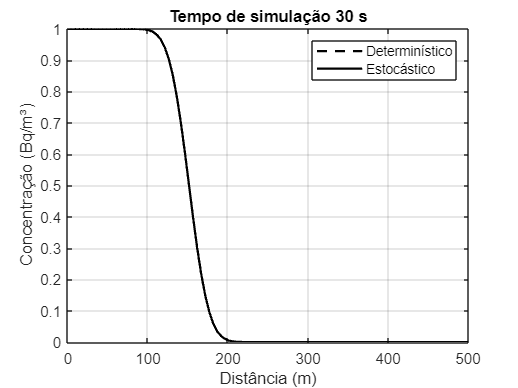

plot(space,explicit(:, TIME), 'k--','LineWidth',1.5);
ylim([0,d.C_x1]);
grid; 

xlabel('Distância (m)'); 
ylabel('Concentração (Bq/m³)');
title("Tempo de simulação " + num2str(TIME*mp.delta_t, 2) + " s");

hold on 

plot(space,sexplicit(:, TIME), 'k-','LineWidth',1.5);
hold off

legend('Determinístico', 'Estocástico')

ERROR_TIME =100

ERROR_TIME = 100

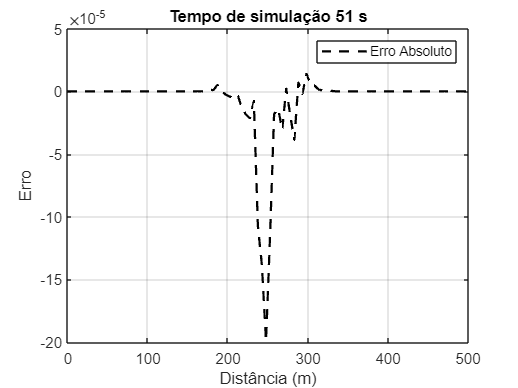

error = explicit - sexplicit;
% relative_error = error./explicit;
% relative_error(relative_error == -Inf) = 0;

plot(space,error(:, ERROR_TIME), 'k--','LineWidth',1.5);
grid; 

xlabel('Distância (m)'); 
ylabel('Erro');
title("Tempo de simulação " + num2str(ERROR_TIME*mp.delta_t, 2) + " s");

% hold on 
% 
% plot(space,relative_error(:, ERROR_TIME), 'k-','LineWidth',1.5);
% hold off
% 
legend('Erro Absoluto')